%% Pure Pursuit Controller Performance Analysis Script
% Comprehensive analysis of Pure Pursuit Controller performance
% This script generates publication-quality plots for controller evaluation

%% Load data and configure environment
fprintf('=== PURE PURSUIT CONTROLLER PERFORMANCE ANALYSIS ===\n');

=== PURE PURSUIT CONTROLLER PERFORMANCE ANALYSIS ===


fprintf('Loading data...\n');

Loading data...



% Load trajectory data
data = load('pure_pursuit_trajectory.mat');
trajectory_points = data.trajectory_points;
pp_params = data.pp_params;
initial_pose = data.initial_pose;
final_pose = data.final_pose;

% Load costmap for visualization
costmap = createParkingLotCostmap();

% Load global waypoints for visualization
global_data = load('GlobalRoutePlan.mat');
routePlan = global_data.routePlan;

% Configure LaTeX interpreter and plot styling - professional academic style
set(0, 'defaultTextInterpreter', 'latex');
set(0, 'defaultAxesTickLabelInterpreter', 'latex');
set(0, 'defaultLegendInterpreter', 'latex');

fontSize = 14;
titleSize = 16;
legendSize = 12;
lineWidth = 2;

% Define color palette
color_red = [0.8, 0.2, 0.2];      % Red for actual/errors
color_yellow = [0.8, 0.6, 0.2];   % Dark yellow for desired/reference
color_blue = [0.2, 0.3, 0.8];     % Dark blue for commands/analysis
color_green = [0.2, 0.7, 0.3];    % Green for lookahead

% Create figure directory if it doesn't exist
if ~exist('figures', 'dir')
    mkdir('figures');
end

%% Data preprocessing - Extract data from timeseries objects
fprintf('Preprocessing timeseries data...\n');

Preprocessing timeseries data...



% Define helper function for timeseries extraction
extractTimeseriesData = @(ts_obj) deal(ts_obj.Time, squeeze(ts_obj.Data));

% Extract all timeseries data
[time_actual_state, data_actual_state] = extractTimeseriesData(out_actual_state);
[time_actual_statedot, data_actual_statedot] = extractTimeseriesData(out_actual_statedot);
[time_v_cmd, data_v_cmd] = extractTimeseriesData(out_v_cmd);
[time_phi_cmd, data_phi_cmd] = extractTimeseriesData(out_phi_cmd);

% Ensure proper data orientation
if size(data_actual_state, 1) == 1
    data_actual_state = data_actual_state';
end
if size(data_actual_statedot, 1) == 1
    data_actual_statedot = data_actual_statedot';
end
if size(data_v_cmd, 1) == 1
    data_v_cmd = data_v_cmd';
end
if size(data_phi_cmd, 1) == 1
    data_phi_cmd = data_phi_cmd';
end

% Check if data was extracted correctly
fprintf('Data dimensions check:\n');

Data dimensions check:


fprintf('  Actual state: %d x %d\n', size(data_actual_state));

  Actual state: 4001 x 3


fprintf('  Actual state time: %d\n', length(time_actual_state));

  Actual state time: 4001


fprintf('  Trajectory points: %d\n', size(trajectory_points, 1));

  Trajectory points: 600



% Determine actual simulation duration
actual_sim_duration = time_actual_state(end);
fprintf('  Actual simulation duration: %.2f s\n', actual_sim_duration);

  Actual simulation duration: 400.00 s



% Extract desired trajectory components
desired_x = trajectory_points(:, 1);
desired_y = trajectory_points(:, 2);
desired_theta = trajectory_points(:, 3);
desired_v = trajectory_points(:, 4);

%% Calculate errors and metrics
fprintf('Calculating tracking errors...\n');

Calculating tracking errors...



% Find closest point on trajectory for each time step
n_points = size(trajectory_points, 1);
closest_indices = zeros(length(time_actual_state), 1);
x_error = zeros(length(time_actual_state), 1);
y_error = zeros(length(time_actual_state), 1);
theta_error = zeros(length(time_actual_state), 1);

for i = 1:length(time_actual_state)
    % Current state
    x_curr = data_actual_state(i, 1);
    y_curr = data_actual_state(i, 2);
    theta_curr = data_actual_state(i, 3);
    
    % Find closest point on trajectory
    distances = sqrt((desired_x - x_curr).^2 + (desired_y - y_curr).^2);
    [~, closest_idx] = min(distances);
    closest_indices(i) = closest_idx;
    
    % Calculate errors
    x_error(i) = x_curr - desired_x(closest_idx);
    y_error(i) = y_curr - desired_y(closest_idx);
    theta_error(i) = wrapToPi(theta_curr - desired_theta(closest_idx));
end

% Calculate Euclidean error
euclidean_error = sqrt(x_error.^2 + y_error.^2);

% Calculate velocity errors
actual_velocity = sqrt(data_actual_statedot(:,1).^2 + data_actual_statedot(:,2).^2);
desired_velocity_interp = zeros(length(time_actual_statedot), 1);
for i = 1:length(time_actual_statedot)
    % Find corresponding desired velocity
    [~, time_idx] = min(abs(time_actual_state - time_actual_statedot(i)));
    desired_velocity_interp(i) = desired_v(closest_indices(time_idx));
end
velocity_error = actual_velocity - desired_velocity_interp;

% Calculate angular velocity
actual_angular_velocity = data_actual_statedot(:,3);
% Calculate desired angular velocity from trajectory
desired_angular_velocity = zeros(length(time_actual_statedot), 1);
for i = 1:length(time_actual_statedot)-1
    % Find corresponding trajectory indices
    [~, time_idx] = min(abs(time_actual_state - time_actual_statedot(i)));
    [~, time_idx_next] = min(abs(time_actual_state - time_actual_statedot(i+1)));
    idx1 = closest_indices(time_idx);
    idx2 = closest_indices(time_idx_next);
    
    if idx1 < n_points && idx2 <= n_points && idx2 > idx1
        % Calculate angular velocity from trajectory
        dt = time_actual_statedot(i+1) - time_actual_statedot(i);
        dtheta = wrapToPi(desired_theta(idx2) - desired_theta(idx1));
        desired_angular_velocity(i) = dtheta / dt;
    end
end
% Handle last point
desired_angular_velocity(end) = desired_angular_velocity(end-1);

% Calculate angular velocity error
angular_velocity_error = actual_angular_velocity - desired_angular_velocity;

% Calculate lookahead distance over time (adaptive)
lookahead_distance = zeros(length(time_actual_state), 1);
for i = 1:length(time_actual_state)
    v_curr = sqrt(data_actual_statedot(min(i, length(time_actual_statedot)), 1)^2 + ...
                  data_actual_statedot(min(i, length(time_actual_statedot)), 2)^2);
    ld = pp_params.lookahead_distance + abs(v_curr) * pp_params.lookahead_time;
    lookahead_distance(i) = max(pp_params.lookahead_min, min(pp_params.lookahead_max, ld));
end

%% 1. TRAJECTORY TRACKING PERFORMANCE WITH MAP VISUALIZATION
fprintf('Generating trajectory tracking visualization...\n');

Generating trajectory tracking visualization...


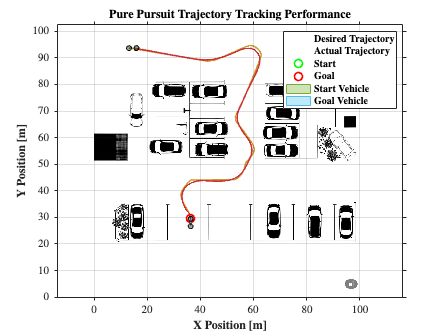


figure('Name', 'Pure Pursuit Trajectory Tracking', 'NumberTitle', 'off', 'Position', [100, 100, 800, 600]);

% Plot cost map
plot(costmap, 'Inflation', 'off');
hold on;

% Plot desired trajectory
plot(desired_x, desired_y, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Trajectory}');

% Plot actual trajectory
if ~isempty(data_actual_state)
    plot(data_actual_state(:,1), data_actual_state(:,2), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Trajectory}');
end

% Plot start and goal positions
initialPose = routePlan{1, 'StartPose'};
finalGoal = routePlan{end, 'EndPose'};
plot(initialPose(1), initialPose(2), 'go', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', '\textbf{Start}');
plot(finalGoal(1), finalGoal(2), 'ro', 'MarkerSize', 10, 'LineWidth', 2, 'DisplayName', '\textbf{Goal}');

% Add vehicle representation at key points (if function exists)
if exist('PlotBicycle', 'file')
    PlotBicycle(initialPose, costmap.CollisionChecker.VehicleDimensions, 'DisplayName', '\textbf{Start Vehicle}');
    PlotBicycle(finalGoal, costmap.CollisionChecker.VehicleDimensions, 'DisplayName', '\textbf{Goal Vehicle}');
end

% Set labels, title and legend with LaTeX formatting
xlabel('\textbf{X Position [m]}', 'FontSize', fontSize);
ylabel('\textbf{Y Position [m]}', 'FontSize', fontSize);
title('\textbf{Pure Pursuit Trajectory Tracking Performance}', 'FontSize', titleSize);

% Set axis limits and legend position
legend('Location', 'northeast', 'FontSize', legendSize);
axis equal;
grid on;
hold off;
set(gca, 'FontSize', fontSize);

% Save figure
saveas(gcf, 'figures/pp_trajectory_tracking.eps', 'epsc');


%% 2. STATE VARIABLES TRACKING COMPARISON
fprintf('Generating state variables comparison...\n');

Generating state variables comparison...


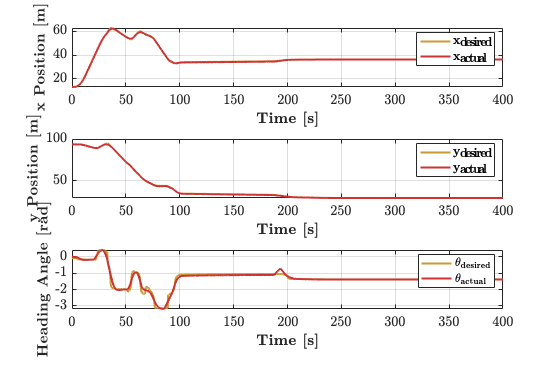

figure('Position', [150, 150, 1200, 800]);

% X position tracking
subplot(3, 1, 1);
plot(time_actual_state, desired_x(closest_indices), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{x_{desired}}$');
hold on;
plot(time_actual_state, data_actual_state(:,1), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{x_{actual}}$');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{x Position [m]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Y position tracking
subplot(3, 1, 2);
plot(time_actual_state, desired_y(closest_indices), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{y_{desired}}$');
hold on;
plot(time_actual_state, data_actual_state(:,2), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{y_{actual}}$');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{y Position [m]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Heading tracking
subplot(3, 1, 3);
plot(time_actual_state, desired_theta(closest_indices), 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{\theta_{desired}}$');
hold on;
plot(time_actual_state, data_actual_state(:,3), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '$\mathbf{\theta_{actual}}$');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Heading Angle [rad]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/pp_state_variables_tracking.eps', 'epsc');


%% 3. TRACKING ERRORS ANALYSIS (MODIFIED - ONLY EUCLIDEAN AND ORIENTATION)
fprintf('Generating tracking errors analysis...\n');

Generating tracking errors analysis...


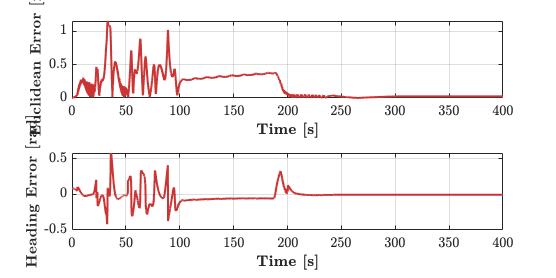


figure('Position', [100, 100, 1200, 600]);

% Plot Euclidean error
subplot(2, 1, 1);
plot(time_actual_state, euclidean_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Euclidean Error [m]}', 'FontSize', fontSize);
%title('\textbf{Position Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_euclidean_error = mean(euclidean_error);
max_euclidean_error = max(euclidean_error);
text(0.02, 200, sprintf('\\textbf{Mean: %.3f m, Max: %.3f m}', mean_euclidean_error, max_euclidean_error),...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Plot theta error
subplot(2, 1, 2);
plot(time_actual_state, theta_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Heading Error [rad]}', 'FontSize', fontSize);
%title('\textbf{Heading Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_theta_error = mean(abs(theta_error));
max_theta_error = max(abs(theta_error));
text(0.02, 200, sprintf('\\textbf{Mean: %.3f rad, Max: %.3f rad}', mean_theta_error, max_theta_error), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

saveas(gcf, 'figures/pp_tracking_errors_analysis.eps', 'epsc');


%% 4. CONTROL COMMANDS AND LOOKAHEAD ANALYSIS
fprintf('Generating control commands and lookahead analysis...\n');

Generating control commands and lookahead analysis...


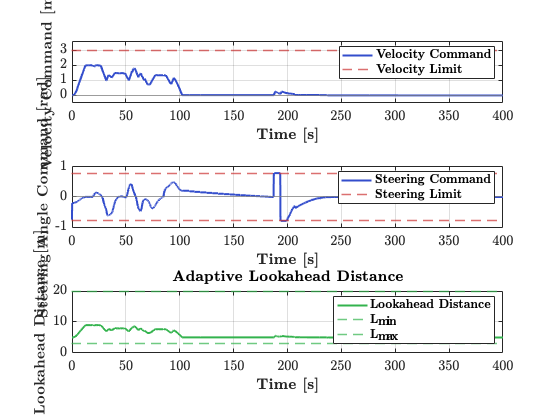

figure('Position', [250, 250, 1200, 900]);

% Velocity command
subplot(3, 1, 1);
plot(time_v_cmd, data_v_cmd, 'Color', color_blue, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Velocity Command}');
hold on;
yline(pp_params.v_max, '--', 'Color', color_red, 'LineWidth', 1.5, 'DisplayName', '\textbf{Velocity Limit}');
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5, 'HandleVisibility', 'off');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Velocity Command [m/s]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
grid on;
ylim([-0.5, pp_params.v_max*1.2]);
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);
% Statistics
mean_v_cmd = mean(data_v_cmd);
max_v_cmd = max(abs(data_v_cmd));
% %text(0.02, 0.15, sprintf('\\textbf{Mean: %.2f m/s, Max: %.2f m/s}', mean_v_cmd, max_v_cmd), ...
%      'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Steering command
subplot(3, 1, 2);
plot(time_phi_cmd, data_phi_cmd, 'Color', color_blue, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Steering Command}');
hold on;
yline(pp_params.phi_max, '--', 'Color', color_red, 'LineWidth', 1.5, 'DisplayName', '\textbf{Steering Limit}');
yline(-pp_params.phi_max, '--', 'Color', color_red, 'LineWidth', 1.5, 'HandleVisibility', 'off');
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5, 'HandleVisibility', 'off');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Steering Angle Command [rad]}', 'FontSize', fontSize);
legend('Location', 'northeast', 'FontSize', legendSize);
grid on;
ylim([-pp_params.phi_max*1.3, pp_params.phi_max*1.3]);
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);
% Statistics
mean_phi_cmd = mean(abs(data_phi_cmd));
max_phi_cmd = max(abs(data_phi_cmd));
saturation_percentage = sum(abs(data_phi_cmd) > pp_params.phi_max*0.95) / length(data_phi_cmd) * 100;
% %text(0.02, 0.15, sprintf('\\textbf{Mean: %.2f°, Max: %.2f°, Saturation: %.1f%%}', ...
%      mean_phi_cmd*180/pi, max_phi_cmd*180/pi, saturation_percentage), ...
%      'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Lookahead distance
subplot(3, 1, 3);
plot(time_actual_state, lookahead_distance, 'Color', color_green, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Lookahead Distance}');
hold on;
yline(pp_params.lookahead_min, '--', 'Color', color_green, 'LineWidth', 1.5, 'DisplayName', '$\mathbf{L_{min}}$');
yline(pp_params.lookahead_max, '--', 'Color', color_green, 'LineWidth', 1.5, 'DisplayName', '$\mathbf{L_{max}}$');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Lookahead Distance [m]}', 'FontSize', fontSize);
title('\textbf{Adaptive Lookahead Distance}', 'FontSize', titleSize);
legend('Location', 'northeast', 'FontSize', legendSize);
grid on;
xlim([0, actual_sim_duration]);
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/pp_control_lookahead_analysis.eps', 'epsc');


%% 5. VELOCITY TRACKING (MODIFIED - LINEAR AND ANGULAR VELOCITIES)
fprintf('Generating velocity tracking analysis...\n');

Generating velocity tracking analysis...


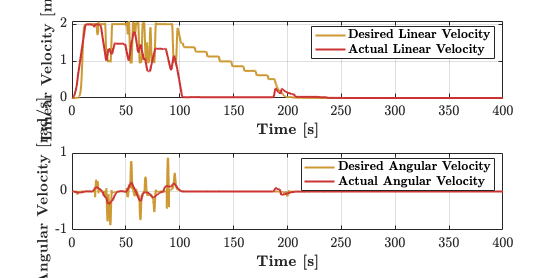


% Apply smoothing if data is long enough
smoothing_span = 21;
if length(actual_velocity) > smoothing_span
    actual_velocity_smooth = smooth(actual_velocity, smoothing_span, 'sgolay', 2);
else
    actual_velocity_smooth = actual_velocity;
end

if length(desired_velocity_interp) > smoothing_span
    desired_velocity_smooth = smooth(desired_velocity_interp, smoothing_span, 'sgolay', 2);
else
    desired_velocity_smooth = desired_velocity_interp;
end

if length(actual_angular_velocity) > smoothing_span
    actual_angular_velocity_smooth = smooth(actual_angular_velocity, smoothing_span, 'sgolay', 2);
else
    actual_angular_velocity_smooth = actual_angular_velocity;
end

if length(desired_angular_velocity) > smoothing_span
    desired_angular_velocity_smooth = smooth(desired_angular_velocity, smoothing_span, 'sgolay', 2);
else
    desired_angular_velocity_smooth = desired_angular_velocity;
end

figure('Position', [300, 300, 1200, 600]);

% Linear velocity tracking
subplot(2, 1, 1);
plot(time_actual_statedot, desired_velocity_smooth, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Linear Velocity}');
hold on;
plot(time_actual_statedot, actual_velocity_smooth, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Linear Velocity}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Linear Velocity [m/s]}', 'FontSize', fontSize);
%title('\textbf{Linear Velocity Tracking}', 'FontSize', titleSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Angular velocity tracking
subplot(2, 1, 2);
plot(time_actual_statedot, desired_angular_velocity_smooth, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Desired Angular Velocity}');
hold on;
plot(time_actual_statedot, actual_angular_velocity_smooth, 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', '\textbf{Actual Angular Velocity}');
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Angular Velocity [rad/s]}', 'FontSize', fontSize);
%title('\textbf{Angular Velocity Tracking}', 'FontSize', titleSize);
legend('Location', 'northeast', 'FontSize', legendSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/pp_velocity_tracking_analysis.eps', 'epsc');


%% 6. VELOCITY ERRORS (NEW FIGURE)
fprintf('Generating velocity errors analysis...\n');

Generating velocity errors analysis...


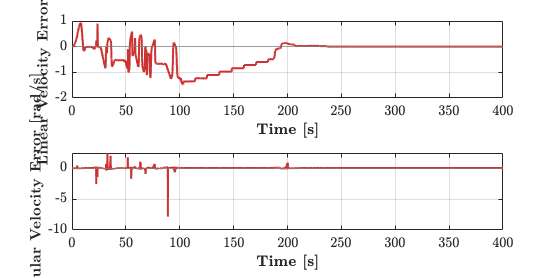


figure('Position', [350, 350, 1200, 600]);

% Linear velocity error
subplot(2, 1, 1);
plot(time_actual_statedot, velocity_error, 'Color', color_red, 'LineWidth', lineWidth);
hold on;
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Linear Velocity Error [m/s]}', 'FontSize', fontSize);
%title('\textbf{Linear Velocity Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_vel_err = mean(abs(velocity_error));
max_vel_err = max(abs(velocity_error));
text(0.02, 200, sprintf('\\textbf{Mean Abs: %.3f m/s, Max Abs: %.3f m/s}', mean_vel_err, max_vel_err), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

% Angular velocity error
subplot(2, 1, 2);
plot(time_actual_statedot, angular_velocity_error, 'Color', color_red, 'LineWidth', lineWidth);
hold on;
yline(0, '-', 'Color', [0.5 0.5 0.5], 'LineWidth', 0.5);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Angular Velocity Error [rad/s]}', 'FontSize', fontSize);
%title('\textbf{Angular Velocity Error}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);
% Add statistics
mean_angular_vel_err = mean(abs(angular_velocity_error));
max_angular_vel_err = max(abs(angular_velocity_error));
text(0.02, 200, sprintf('\\textbf{Mean Abs: %.3f rad/s, Max Abs: %.3f rad/s}', mean_angular_vel_err, max_angular_vel_err), ...
     'Units', 'normalized', 'FontSize', fontSize-2, 'BackgroundColor', 'white');

saveas(gcf, 'figures/pp_velocity_errors_analysis.eps', 'epsc');


%% 7. EUCLIDEAN ERROR OVER TIME
fprintf('Generating Euclidean error plot...\n');

Generating Euclidean error plot...


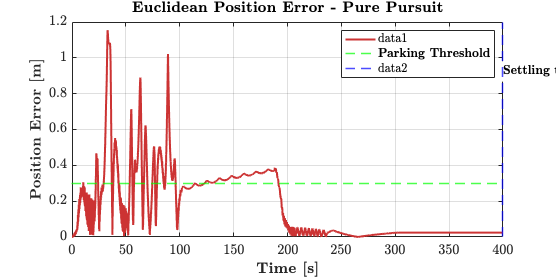

figure('Position', [400, 400, 800, 400]);

plot(time_actual_state, euclidean_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Position Error [m]}', 'FontSize', fontSize);
title('\textbf{Euclidean Position Error - Pure Pursuit}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Add parking thresholds
hold on;
yline(pp_params.parking_distance_threshold, '--g', 'LineWidth', 1.5, 'DisplayName', '\textbf{Parking Threshold}');

% Add settling time marker if applicable
settling_threshold = 0.5;
settling_idx = find(euclidean_error < settling_threshold, 1, 'last');
if ~isempty(settling_idx)
    xline(time_actual_state(settling_idx), '--b', 'LineWidth', 1.5);
    text(time_actual_state(settling_idx), max(euclidean_error)*0.8, ...
         sprintf('\\textbf{Settling time: %.1f s}', time_actual_state(settling_idx)), ...
         'FontSize', fontSize-2, 'BackgroundColor', 'white');
end

legend('Location', 'northeast', 'FontSize', legendSize);

saveas(gcf, 'figures/pp_euclidean_error.eps', 'epsc');


%% 8. STATISTICAL ANALYSIS
fprintf('Generating statistical analysis...\n');

Generating statistical analysis...


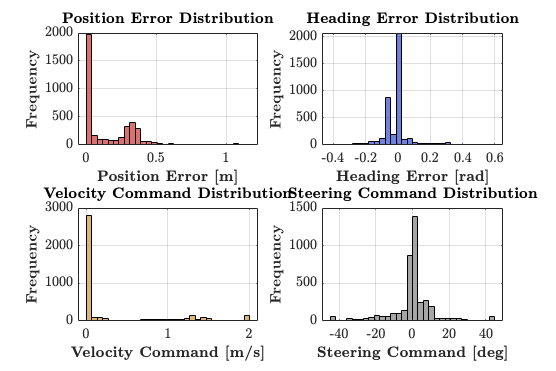

figure('Position', [450, 450, 1200, 800]);

% Position error distribution
subplot(2, 2, 1);
histogram(euclidean_error, 30, 'FaceColor', color_red, 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Position Error [m]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Position Error Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

% Heading error distribution
subplot(2, 2, 2);
histogram(theta_error, 30, 'FaceColor', color_blue, 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Heading Error [rad]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Heading Error Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

% Control effort distribution
subplot(2, 2, 3);
histogram(data_v_cmd, 30, 'FaceColor', color_yellow, 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Velocity Command [m/s]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Velocity Command Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

% Steering effort distribution
subplot(2, 2, 4);
histogram(data_phi_cmd*180/pi, 30, 'FaceColor', [0.5 0.5 0.5], 'EdgeColor', 'black', 'FaceAlpha', 0.7);
xlabel('\textbf{Steering Command [deg]}', 'FontSize', fontSize);
ylabel('\textbf{Frequency}', 'FontSize', fontSize);
title('\textbf{Steering Command Distribution}', 'FontSize', titleSize);
grid on;
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/pp_statistical_analysis.eps', 'epsc');


%% 9. PURE PURSUIT SPECIFIC ANALYSIS
fprintf('Generating Pure Pursuit specific analysis...\n');

Generating Pure Pursuit specific analysis...


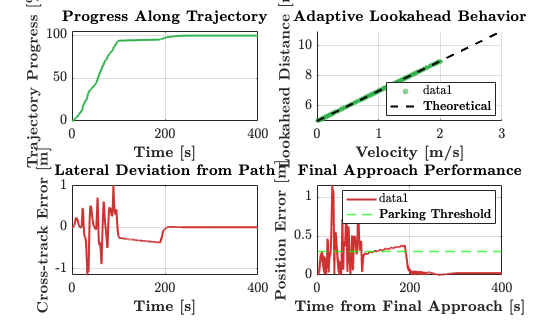

figure('Position', [500, 500, 1200, 700]);

% Progress along trajectory
subplot(2, 2, 1);
plot(time_actual_state, closest_indices / n_points * 100, 'Color', color_green, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Trajectory Progress [\%]}', 'FontSize', fontSize);
title('\textbf{Progress Along Trajectory}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
ylim([0, 105]);
grid on;
set(gca, 'FontSize', fontSize);

% Lookahead vs velocity relationship
subplot(2, 2, 2);
scatter(actual_velocity, lookahead_distance(1:length(actual_velocity)), 20, color_green, 'filled', 'MarkerFaceAlpha', 0.6);
hold on;
% Theoretical relationship
v_theory = linspace(0, pp_params.v_max, 100);
ld_theory = pp_params.lookahead_distance + v_theory * pp_params.lookahead_time;
ld_theory = max(pp_params.lookahead_min, min(pp_params.lookahead_max, ld_theory));
plot(v_theory, ld_theory, 'k--', 'LineWidth', 2, 'DisplayName', '\textbf{Theoretical}');
xlabel('\textbf{Velocity [m/s]}', 'FontSize', fontSize);
ylabel('\textbf{Lookahead Distance [m]}', 'FontSize', fontSize);
title('\textbf{Adaptive Lookahead Behavior}', 'FontSize', titleSize);
legend('Location', 'southeast', 'FontSize', legendSize);
grid on;
set(gca, 'FontSize', fontSize);

% Cross-track error (lateral deviation)
subplot(2, 2, 3);
cross_track_error = zeros(length(time_actual_state), 1);
for i = 1:length(time_actual_state)
    if closest_indices(i) < n_points
        % Vector from current to next waypoint
        dx = desired_x(closest_indices(i)+1) - desired_x(closest_indices(i));
        dy = desired_y(closest_indices(i)+1) - desired_y(closest_indices(i));
        % Normalize
        d_norm = sqrt(dx^2 + dy^2);
        if d_norm > 1e-6
            dx = dx / d_norm;
            dy = dy / d_norm;
            % Cross product for lateral error
            cross_track_error(i) = -dy * x_error(i) + dx * y_error(i);
        end
    end
end
plot(time_actual_state, cross_track_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}', 'FontSize', fontSize);
ylabel('\textbf{Cross-track Error [m]}', 'FontSize', fontSize);
title('\textbf{Lateral Deviation from Path}', 'FontSize', titleSize);
xlim([0, actual_sim_duration]);
grid on;
set(gca, 'FontSize', fontSize);

% Final approach analysis
subplot(2, 2, 4);
final_approach_idx = find(euclidean_error < pp_params.final_approach_distance, 1);
if ~isempty(final_approach_idx)
    time_final = time_actual_state(final_approach_idx:end) - time_actual_state(final_approach_idx);
    error_final = euclidean_error(final_approach_idx:end);
    plot(time_final, error_final, 'Color', color_red, 'LineWidth', lineWidth);
    hold on;
    yline(pp_params.parking_distance_threshold, '--g', 'LineWidth', 1.5, 'DisplayName', '\textbf{Parking Threshold}');
    xlabel('\textbf{Time from Final Approach [s]}', 'FontSize', fontSize);
    ylabel('\textbf{Position Error [m]}', 'FontSize', fontSize);
    title('\textbf{Final Approach Performance}', 'FontSize', titleSize);
    legend('Location', 'northeast', 'FontSize', legendSize);
    grid on;
    set(gca, 'FontSize', fontSize);
end

saveas(gcf, 'figures/pp_specific_analysis.eps', 'epsc');


%% 10. CONTROLLER PERFORMANCE DASHBOARD
fprintf('Generating controller performance dashboard...\n');

Generating controller performance dashboard...


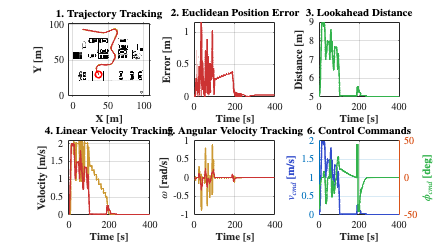


figure('Name', 'Pure Pursuit Performance Dashboard', 'Position', [100, 100, 1600, 900]);

% --- 1. Trajectory Tracking on Map ---
subplot(2, 3, 1);
plot(costmap, 'Inflation', 'off');
hold on;
plot(desired_x, desired_y, 'Color', color_yellow, 'LineWidth', lineWidth, 'DisplayName', 'Desired');
plot(data_actual_state(:,1), data_actual_state(:,2), 'Color', color_red, 'LineWidth', lineWidth, 'DisplayName', 'Actual');
plot(initial_pose(1), initial_pose(2), 'go', 'MarkerSize', 8, 'LineWidth', 2);
plot(final_pose(1), final_pose(2), 'ro', 'MarkerSize', 8, 'LineWidth', 2);
xlabel('\textbf{X [m]}'); ylabel('\textbf{Y [m]}');
title('\textbf{1. Trajectory Tracking}');
axis equal; grid on;
set(gca, 'FontSize', fontSize-2);

% --- 2. Euclidean Position Error ---
subplot(2, 3, 2);
plot(time_actual_state, euclidean_error, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Error [m]}');
title('\textbf{2. Euclidean Position Error}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 3. Lookahead Distance ---
subplot(2, 3, 3);
plot(time_actual_state, lookahead_distance, 'Color', color_green, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Distance [m]}');
title('\textbf{3. Lookahead Distance}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 4. Velocity Tracking ---
subplot(2, 3, 4);
plot(time_actual_statedot, desired_velocity_smooth, 'Color', color_yellow, 'LineWidth', lineWidth);
hold on;
plot(time_actual_statedot, actual_velocity_smooth, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{Velocity [m/s]}');
title('\textbf{4. Linear Velocity Tracking}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 5. Angular Velocity Tracking ---
subplot(2, 3, 5);
plot(time_actual_statedot, desired_angular_velocity_smooth, 'Color', color_yellow, 'LineWidth', lineWidth);
hold on;
plot(time_actual_statedot, actual_angular_velocity_smooth, 'Color', color_red, 'LineWidth', lineWidth);
xlabel('\textbf{Time [s]}'); ylabel('\textbf{$\omega$ [rad/s]}');
title('\textbf{5. Angular Velocity Tracking}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

% --- 6. Control Commands ---
subplot(2, 3, 6);
yyaxis left
plot(time_v_cmd, data_v_cmd, 'Color', color_blue, 'LineWidth', lineWidth);
ylabel('\textbf{$v_{cmd}$ [m/s]}', 'Color', color_blue);
yyaxis right
plot(time_phi_cmd, data_phi_cmd*180/pi, 'Color', color_green, 'LineWidth', lineWidth);
ylabel('\textbf{$\phi_{cmd}$ [deg]}', 'Color', color_green);
xlabel('\textbf{Time [s]}');
title('\textbf{6. Control Commands}');
xlim([0, actual_sim_duration]); grid on;
set(gca, 'FontSize', fontSize-2);

saveas(gcf, 'figures/pp_performance_dashboard.eps', 'epsc');




fprintf('Generating KPI summary plot...\n');

Generating KPI summary plot...


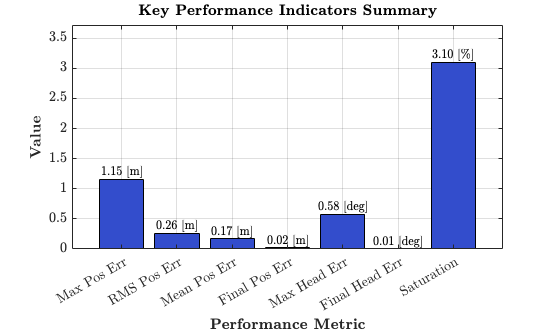


% Calculate KPIs
kpi_max_pos_err = max(euclidean_error);
kpi_rms_pos_err = rms(euclidean_error);
kpi_mean_pos_err = mean(euclidean_error);
kpi_final_pos_err = euclidean_error(end);
kpi_max_heading_err = max(abs(theta_error));
kpi_final_heading_err = abs(theta_error(end));
kpi_saturation = saturation_percentage;

figure('Position', [550, 550, 1000, 600]);

% Create KPI names and values
kpi_names = categorical({'Max Pos Err', 'RMS Pos Err', 'Mean Pos Err', 'Final Pos Err', ...
                        'Max Head Err', 'Final Head Err', 'Saturation'});
kpi_names = reordercats(kpi_names, {'Max Pos Err', 'RMS Pos Err', 'Mean Pos Err', 'Final Pos Err', ...
                                    'Max Head Err', 'Final Head Err', 'Saturation'});
kpi_values = [kpi_max_pos_err, kpi_rms_pos_err, kpi_mean_pos_err, kpi_final_pos_err, ...
              kpi_max_heading_err, kpi_final_heading_err, kpi_saturation];
kpi_units = {'[m]', '[m]', '[m]', '[m]', '[deg]', '[deg]', '[\%]'};

% Create bar plot
bar_plot = bar(kpi_names, kpi_values, 'FaceColor', color_blue);

% Add value labels on bars
xtips = bar_plot.XEndPoints;
ytips = bar_plot.YEndPoints;
for i = 1:length(ytips)
    text(xtips(i), ytips(i), sprintf('%.2f %s', kpi_values(i), kpi_units{i}), ...
         'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', ...
         'FontSize', fontSize-2, 'FontWeight', 'bold');
end

xlabel('\textbf{Performance Metric}', 'FontSize', fontSize);
ylabel('\textbf{Value}', 'FontSize', fontSize);
title('\textbf{Key Performance Indicators Summary}', 'FontSize', titleSize);
grid on;
ylim([0, max(ytips)*1.2]);
set(gca, 'FontSize', fontSize);

saveas(gcf, 'figures/kpi_summary_bicycle.eps', 'epsc');

function angle = wrapToPi(angle)
    % Wrap angle to [-pi, pi]
    angle = mod(angle + pi, 2*pi) - pi;
end